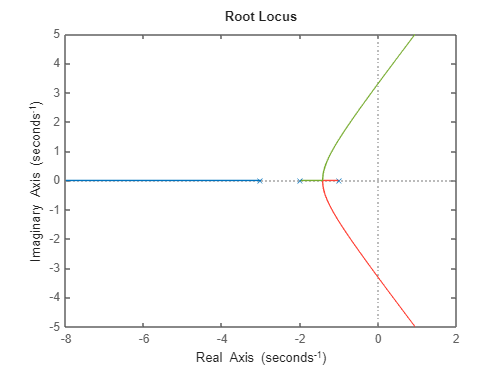

numG = [1];
den_1=[1 1];
den_2=[1 2];
den_3=[1 3];
den_T = conv(den_1,den_2);
denG = conv(den_T,den_3);
G = tf(numG, denG);
rlocus(G)


Kp = 60;     
Ki = 0;     
Kd = 0;      

numC = [Kd, Kp, Ki];
denC = [1, 0];
C = tf(numC, denC)


C =
 
  60 s
  ----
   s
 
Continuous-time transfer function.
Model Properties


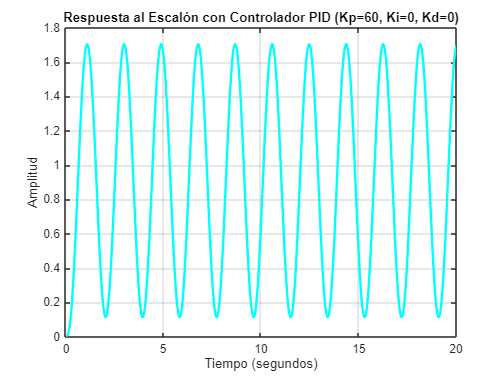


T = feedback(C * G, 1);
t = 0:0.01:20; 
[y, ~] = step(T, t); 
figure; 

plot(t, y, 'c-', 'LineWidth', 2);
grid on;
title(['Respuesta al Escalón con Controlador PID (Kp=', num2str(Kp), ', Ki=', num2str(Ki), ', Kd=', num2str(Kd), ')']);
ylabel('Amplitud');
xlabel('Tiempo (segundos)');

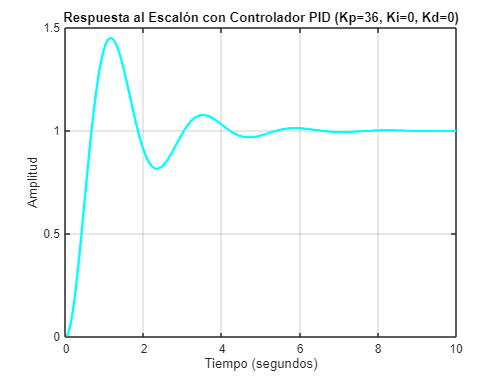

k_u=Kp;
P_u=1.87;
Kp = 0.6*k_u;     
Ti = 0.5*P_u;     
Td = P_u/8;      
C = pid(Kp, Kp/Ti, Kp*Td);

T = feedback(C * G, 1);
t = 0:0.01:10; 
[y, ~] = step(T, t); 
figure; 

plot(t, y, 'c-', 'LineWidth', 2);
grid on;
title(['Respuesta al Escalón con Controlador PID (Kp=', num2str(Kp), ', Ki=', num2str(Ki), ', Kd=', num2str(Kd), ')']);
ylabel('Amplitud');
xlabel('Tiempo (segundos)');